[x_hermite, w_hermite] = Func_GaussHermite_2(22);

A0 = 1;
A_mod = 1;

mu_e = 0;
sigma_e = 0.05;

rho_e = 0.99;

Ahp = A_mod * hl * rho_e;

# Approximate pdf_z

term1 = phi_mod^2 /2 * exp(-0.5 * Rytov^2 * phi_mod^4) * Rytov/sqrt(pi*(1-rho_e^2)*sigma_e^2);

term2 = @(z,x,w) w .* exp(x.^2) .* exp(sqrt(2)*Rytov.*x*phi_mod^2) .* erfc(x) .* ...
        exp(-(-Ahp.* exp(sqrt(2)*Rytov.*x-mu) + z - mu_e).^2 ./ (2*(1-rho_e^2)*sigma_e^2));

pdf_z_apx = @(z) term1*sum(term2(z,x_hermite, w_hermite))

pdf_z_apx = function_handle with value:
    @(z)term1*sum(term2(z,x_hermite,w_hermite))


syms z
vpaintegral(pdf_z_apx, z, -1e1000, 1e1000)

$$ans = 0.118887$$

# Exact pdf_z

term1 = phi_mod^2/(2*Ahp^(phi_mod^2)) * exp(0.5*Rytov^2*phi_mod^2*(1+phi_mod^2)) * 1/sqrt(2*pi*sigma_e^2*(1-rho_e^2));

func = @(z,x) x^(phi_mod^2-1) .* erfc((log(x./Ahp) + mu)/sqrt(2)/Rytov) .* ... 
        exp(-(z - x - mu_e).^2 ./ (2*sigma_e^2 * (1-rho_e^2)));

syms x
pdf_z_ext_2 = @(z) term1 .* vpaintegral(func(z,x),x, 0, inf); 
% syms z
% vpaintegral(pdf_z_ext_2, z, 0, inf)

term1 = phi_mod^2 /2 * exp(-0.5 * Rytov^2 * phi_mod^4) * Rytov/sqrt(pi*(1-rho_e^2)*sigma_e^2);

syms x
term2 = @(z) exp(sqrt(2)*Rytov.*x*phi_mod^2) .* erfc(x) .* ...
        exp(-(-Ahp.* exp(sqrt(2)*Rytov.*x-mu) + z - mu_e).^2 ./ (2*(1-rho_e^2)*sigma_e^2));

pdf_z_ext = @(z) term1* vpaintegral(term2(z), x, -inf, inf);
% syms z
% vpaintegral(pdf_z_ext, z, 0, inf)

N_sample = 1e6;
%----hp----%
ha     = lognrnd(-(Rytov^2)/2,Rytov,[1 N_sample]); %Turbulence 
%----hp----%
x_dir      = normrnd(rho_x,sigma_jt_x,[1 N_sample]);         %Horizontal displacement (Gaussian)
y_dir      = normrnd(rho_y,sigma_jt_y,[1 N_sample]);         %Vertical displacement (Gaussian)
r      = sqrt(x_dir.^2 + y_dir.^2);
hp     = A0*exp(-2*r.^2/w_Leq^2);
%----h----%
h_sim_arr      = ha.*hp*hl;

error = normrnd(mu_e, sigma_e, [1 N_sample]);

z_sim_arr = rho_e.*h_sim_arr + sqrt(1 - rho_e^2).*error;

[den, xi] = ksdensity(z_sim_arr);
xi = xi(xi > 0);
den = den(xi > 0);
den_anal = pdf_z_ext(xi);
den_apx = pdf_z_apx(xi);
den_ext_2 = pdf_z_ext_2(xi);

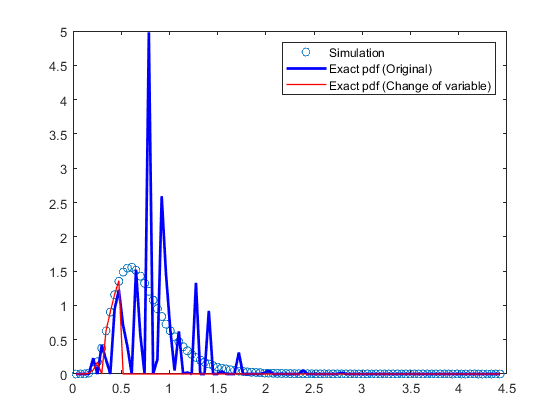

plot(xi, den, 'o', 'DisplayName', 'Simulation'), hold on
% plot(xi, den_apx, 'DisplayName', 'Aprrox pdf')
plot(xi, den_ext_2, 'b', 'DisplayName', 'Exact pdf (Original)', 'LineWidth', 2)
plot(xi, den_anal, 'r', 'DisplayName', 'Exact pdf (Change of variable)', 'LineWidth', 1), hold off
hold off
legend()

pdf_y = @(y) 1/sqrt(2*pi*sigma_e^2*(1-rho_e^2)) * exp(-y.^2 ./ (2*sigma_e^2 * (1-rho_e^2)));
integral(pdf_y, -1e1000, 1e1000)

ans = 1.0000

pdf_x = @(x) phi_mod^2/(2*Ahp^(phi_mod^2)) * exp(0.5*Rytov^2*phi_mod^2*(1+phi_mod^2)) .* ...
        x.^(phi_mod^2-1) .* erfc((log(x./Ahp) + mu)/sqrt(2)/Rytov);
integral(pdf_x, 0, 1e1000)

ans = 1.0000

% pdf of x with change of variable to y
pdf_y = @(y) phi_mod^2 /2 * exp(-0.5 * Rytov^2 * phi_mod^4) * sqrt(2) * Rytov ...
    .* exp(sqrt(2)*Rytov.*y*phi_mod^2) .* erfc(y);
integral(pdf_y, -1e1000, 1e1000)

ans = NaN

N_sample = 1e6;

N_init = 200;

N_sim = N_sample - N_init;

%----hp----%
ha     = lognrnd(-(Rytov^2)/2,Rytov,[1 N_sample]); %Turbulence 
%----hp----%
x_dir      = normrnd(rho_x,sigma_jt_x,[1 N_sample]);         %Horizontal displacement (Gaussian)
y_dir      = normrnd(rho_y,sigma_jt_y,[1 N_sample]);         %Vertical displacement (Gaussian)
r      = sqrt(x_dir.^2 + y_dir.^2);
hp     = A0*exp(-2*r.^2/w_Leq^2);
%----h----%
h_sim_arr      = ha.*hp*hl;
x_h = h_sim_arr .* rho_e;

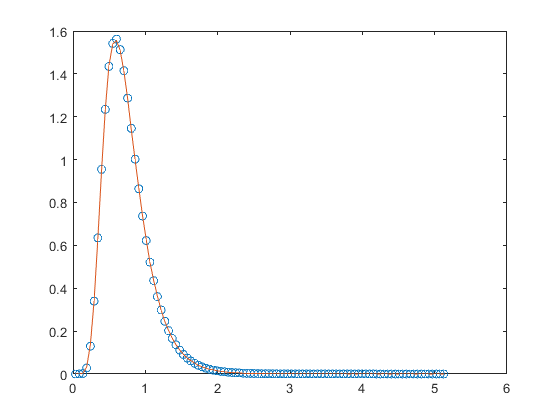

[den, xi] = ksdensity(x_h);
xi = xi(xi > 0);
den = den(xi > 0);
y_h = pdf_x(xi);
plot(xi, y_h, 'o'), hold on
plot(xi, den)
hold off